# General sensitivity analysis for model validation

## Model definition 

First, we define the factor (initial values and parameters) names followed by the model outputs.

VarNames={'N_0','E^3_0','P_0','J_1','J_{L}','D','R_j','RJ_L'};

OutNames={'S_f','S_q','E_f','E_q','L_f','L_q','H_f','H_q','J','D',...
        'R','T','RJH','RJL','RJ','Tot','JH','JL','J_{~P}','J_{P}'};

ParNames={'\beta_L','\beta_T', '\beta_P', '\phi_{EP}',...
            '\lambda_{fq}', '\vartheta_E','\gamma_L', 'k_L',...
            'k_P', '\phi_T','\lambda_{qf}', '\psi_e', '\phi_{PH}',...
            '\delta','m','\eta_L', '\vartheta_P','\gamma_H', 'z',...
            '\phi_{PL}','\eta_\vartheta','nons','a_L','b_L',...
            'a_\mu','b_\mu','\mu','a_H','b_H','\nu','time'};

FullNames = [VarNames,ParNames];

ModelName = 'eva02';

Then, we define the interval values for model factors; their values are according to the parameter nature and some studies in literature, for more information about it, see the main paper document.

Range1 = [
    5e7 5.8e7;  %N_0
    0 2000;     %E^2_0
    0 400;      %P_0
    1 400;      %J_1
    0 0;        %J_L
    0 17;       %D
    0 28;       %R_j
    0 0;        %RJ_L
    ];

Range2=[
    0.7 0.9;    %beta_L
    0   1;      %beta_T          
    0.2 0.6;    %beta_P
    0	8;      %phi_{EP}
    0	1;      %lambda_{fq}
    0	1;      %vartheta_E
    0   1;      %gamma_L
    1   10;     %k_L
    1   1;      %k_P
    1	8;      %phi_T
    0	1;      %lambda_{qf}
    0	0;      %psi_e
    0	3;      %phi_{PH}
    0   0.15;   %delta
    0   0;      %m
    0   1;      %eta_L
    0   1;      %vartheta_P
    0   1;      %gamma_H 
    0   30;     %z 
    0   3;      %phi_{PL}
    0   1;      %eta_vartheta
    0   0;      %nons
    1   15;     %a_L
    1   15;     %b_L
    1   15;     %a_mu
    1   15;     %b_mu
    0   1;      %mu
    1   15;     %a_H
    1   15;     %b_H
    0  500;     %nu
    25  60      %time
    ];

RangeT = [Range1;Range2];


Finally, we define the real data domain

D = length(ydata(1,:));
Domain = [0 D-1];
xdata = 0:D-1;

and create the struture data that manage the model simulations, estimations, and other methodologies

[T,~]=gsua_dataprep(ModelName,RangeT,'domain',Domain,'names',FullNames,'out_names',OutNames);

Setting environment to work with user-defined function


## Sensitivity analysis for estimation intervals

We define the output that we apply to the sensitivity analysis, in this case:  **9**, actual cases.

T.Properties.CustomProperties.output = 9;

Number of samples and the generation of the design matrix (combination of factor values)

N = 2000000;
M = gsua_dmatrix(T,N,'Method','Sobol');

T_sa = gsua_sa(M,T);
IndexSA = T_sa.Si;

save('GeneralSAIndex.mat','IndexSA')

Validation that the number of samples is enough to analyze the sensitivity analysis results.

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 0.9924

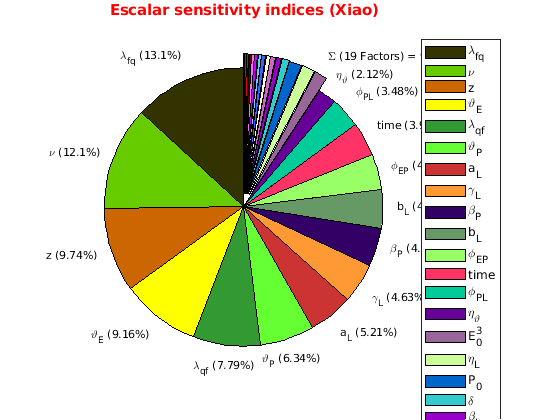

clf
gsua_plot('Pie',T_sa,T_sa.STi)

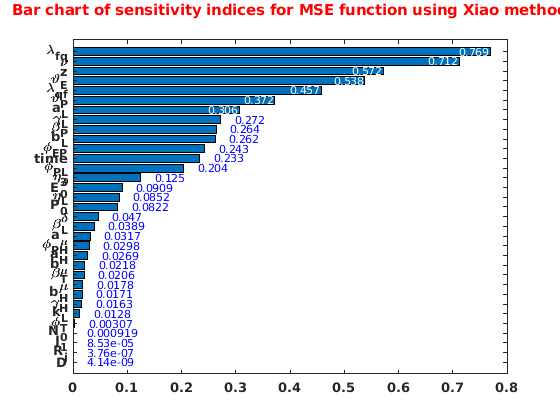

clf
gsua_plot('Bar',T_sa,T_sa.STi)

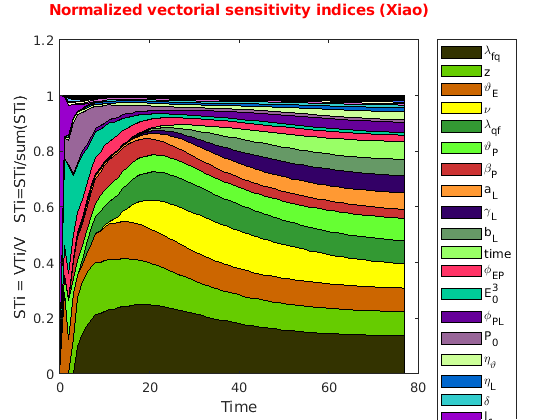

clf
gsua_plot('TotalSensitivityArea',T_sa,T_sa.STi_vec,xdata);